%% Prelims
libs = [ ...
    "REPOS_ONLINE/nihelp", ...
    "REPOS_ONLINE/BrainEigenmodes", ...
    "REPOS_ONLINE/plotSurfaceROIBoundary", ...
    "REPOS_ONLINE/BMH_utils_matlab" ...
];
for ii = libs; addpath(genpath("/fs03/kg98/mehul/"+ii)); end
clear ii libs

bePath = what('BrainEigenmodes').path; % brain eigenmodes path

%% Import data
[lh_verts_sphere, lh_faces] = read_vtk(append(bePath,"/data/template_surfaces_volumes/fsLR_32k_sphere-lh.vtk"));
cortexMask = logical(readmatrix(append(bePath, "/data/template_surfaces_volumes/fsLR_32k_cortex-lh_mask.txt")));
dataModes = readmatrix(append(bePath,"/data/examples/fsLR_32k_midthickness-lh_emode_50.txt"));
% dataModes = readmatrix('james-code_sphere_emodes_yeo_noMask.txt');

dataModes = dataModes(:,1:49);
% dataModes = [dataModes, zeros(size(dataModes, 1), 5)];

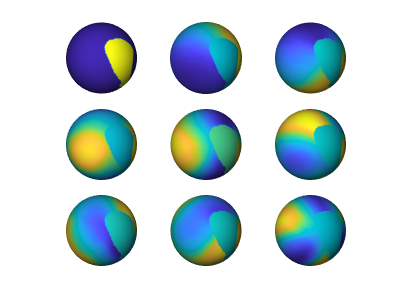

%% Plot original modes
figure;
plotBrain(lh_verts_sphere', lh_faces', [], dataModes(:, 1:9));

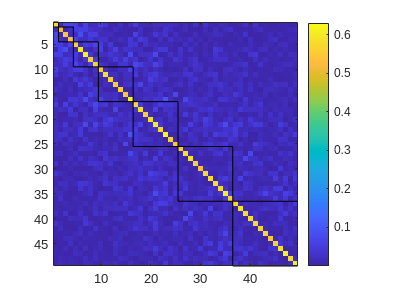


figure; 
imagescmode(abs(dataModes.' * dataModes));

% 
% dataModes2 = dataModes;
% 
% for ii = 2:5
%     rot = makeRandomRotationMatrix(2*ii-1);
%     dataModes2(:, getEigengroupIdx(ii)) = dataModes(:, getEigengroupIdx(ii))*rot';
% end
% 
% figure; 
% plotBrain(lh_verts_sphere, lh_faces, ones(length(lh_verts_sphere),1), dataModes2);
% 
% 
% figure; 
% imagesc(dataModes2.' * dataModes2);


%% Eigenstrap whole thing
tic;
dataModes3 = eigenstrap(dataModes);
toc;

Elapsed time is 0.061781 seconds.


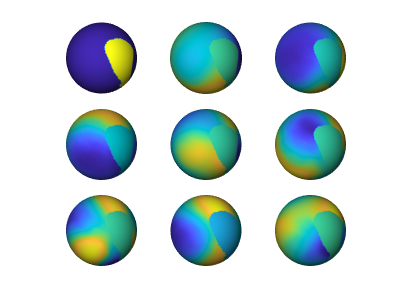


figure; 
plotBrain(lh_verts_sphere', lh_faces', [], dataModes3(:, 1:9));

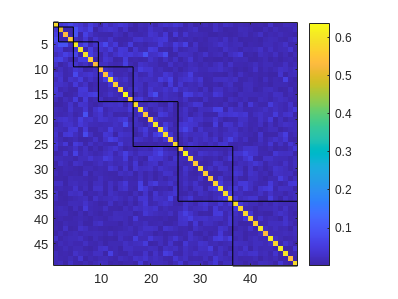


figure; 
imagescmode(abs(dataModes3.' * dataModes3));

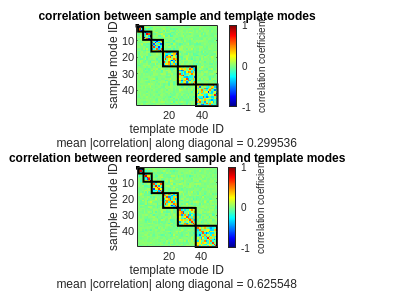


matchModes(dataModes3, dataModes, 'showFigures', 1);

%% Eigenstrap with mask

tic;
dataModes4 = eigenstrap(dataModes, cortexMask);
toc;

Elapsed time is 0.026795 seconds.


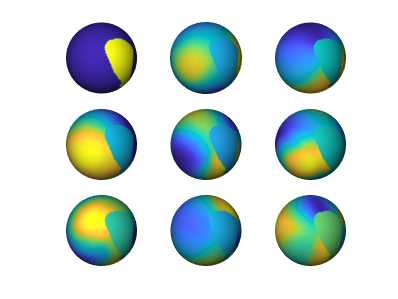


figure; 
plotBrain('lh', {lh_verts_sphere', lh_faces', [], dataModes4(:,1:9)}, 'view', 'lm');

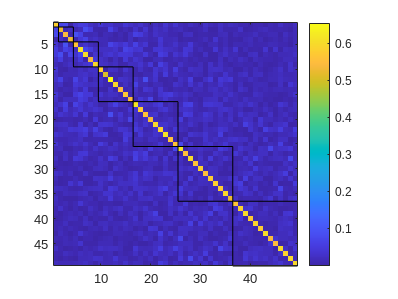

% plotBrain('lh', {vertsMasked, facesMasked, ones(length(vertsMasked),1), dataModes4(:,1:9)}, 'view', 'lm');


% figure; 
% imagescmode(abs(dataModes.' * dataModes));
% 
% figure; 
% imagescmode(abs(dataModes(cortexMask,:).' * dataModes(cortexMask,:)));


figure; 
imagescmode(abs(dataModes4.' * dataModes4));

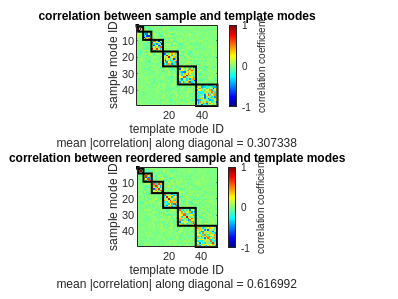


matchModes(dataModes4, dataModes, 'showFigures', 1);